% Change the solver
% clear all
% solverOK=changeCobraSolver('ibm_cplex','all');

## Create a new COBRA model with the following reactions

ReactionFormulas = {'-> A',' -> B','A -> C','B -> C','B -> D','C ->','D ->'};
ReactionNames = {'v1','v2','v3','v4','v5','v6','v7'};
GeneNames={'Gene1','Gene2','Gene3','Gene4','Gene5','Gene6','Gene7'};

orig_model = createModel(ReactionNames, ReactionNames, ReactionFormulas,'grRuleList',GeneNames);

Adding the following Metabolites to the model:
A[c]
B[c]
C[c]
D[c]
addMultipleReactions: Adding the following reactions to the model:
v1		->	A[c] 
v2		->	B[c] 
v3	A[c] 	->	C[c] 
v4	B[c] 	->	C[c] 
v5	B[c] 	->	D[c] 
v6	C[c] 	->	
v7	D[c] 	->	



disp('S'); full(orig_model.S)

S


ans =      1     0    -1     0     0     0     0
     0     1     0    -1    -1     0     0
     0     0     1     1     0    -1     0
     0     0     0     0     1     0    -1


disp('metabolites'); orig_model.mets

metabolites


ans = 4×1 cell array
    {'A[c]'}
    {'B[c]'}
    {'C[c]'}
    {'D[c]'}


disp('reactions'); orig_model.rxns

reactions


ans = 7×1 cell array
    {'v1'}
    {'v2'}
    {'v3'}
    {'v4'}
    {'v5'}
    {'v6'}
    {'v7'}


disp(' ') 

disp('boundaries:') 

boundaries:


disp([orig_model.rxns num2cell(orig_model.lb) num2cell(orig_model.ub)])

    'v1'    [0]    [1000]
    'v2'    [0]    [1000]
    'v3'    [0]    [1000]
    'v4'    [0]    [1000]
    'v5'    [0]    [1000]
    'v6'    [0]    [1000]
    'v7'    [0]    [1000]



disp('Genes:') 

Genes:


disp([orig_model.genes])

    'Gene1'
    'Gene2'
    'Gene3'
    'Gene4'
    'Gene5'
    'Gene6'
    'Gene7'



model=orig_model;
% Define system boundaries
model = changeRxnBounds(model,{'v1','v2'},[1 1],'b'); 
% finally print reactions in the model
disp(' ')

disp('model contains now the following reactions:')

model contains now the following reactions:


printRxnFormula(model,model.rxns);

v1		->	A[c] 
v2		->	B[c] 
v3	A[c] 	->	C[c] 
v4	B[c] 	->	C[c] 
v5	B[c] 	->	D[c] 
v6	C[c] 	->	
v7	D[c] 	->	


disp(' ')

disp('Boundaries:')

Boundaries:


disp([model.rxns num2cell(model.lb) num2cell(model.ub)])

    'v1'    [1]    [   1]
    'v2'    [1]    [   1]
    'v3'    [0]    [1000]
    'v4'    [0]    [1000]
    'v5'    [0]    [1000]
    'v6'    [0]    [1000]
    'v7'    [0]    [1000]



## Optimization

model = changeObjective(model,'v6',1);
model.c

ans =      0
     0
     0
     0
     0
     1
     0


solution = optimizeCbModel(model);
disp(' ')

disp('FBA solution:')

FBA solution:


printFluxVector(model,solution.x);

v1                  	           1
v2                  	           1
v3                  	           1
v4                  	           1
v5                  	           0
v6                  	           2
v7                  	          -0


Start_time = '2023_3_21_8_48_11.447'

Biograph object with 11 nodes and 10 edges.


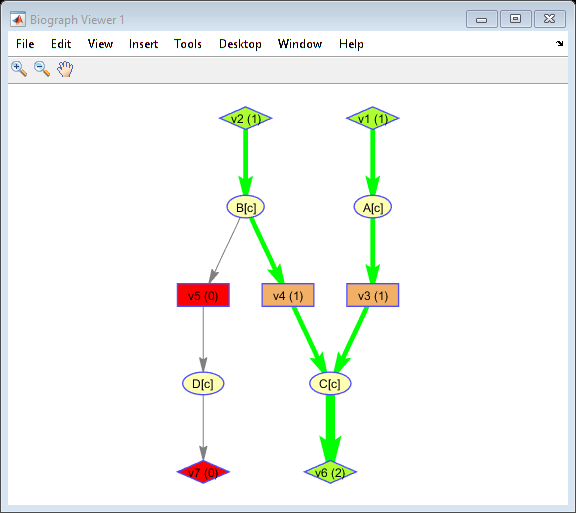

End_time = '2023_3_21_8_48_12.309'

Total_time = '0_0_0_0_0_0.862'


%Vizualize the flux solution
[Involved_mets, Dead_ends] = draw_by_rxn(model, model.rxns, 'true', 'struc', {''}, {''}, solution.x);


%Interactive flux analysis
surfNet(model, 'A[c]', 0, solution.x)


Met #1  A[c], A[c]

Consuming reactions with non-zero fluxes :
  #3  v3 (1), Bd: -0 / 1000, v3, grRules: Gene3
A[c]   ->   C[c] 
Producing reactions with non-zero fluxes :
  #1  v1 (1), Bd: 1 / 1, v1, grRules: Gene1
A[c] 

Show previous steps...


## Flux Variability Analysis (FVA)

model = changeObjective(model,'v6',0)

model = struct with fields:
          rxns: {7×1 cell}
             S: [4×7 double]
            lb: [7×1 double]
            ub: [7×1 double]
             c: [7×1 double]
          mets: {4×1 cell}
             b: [4×1 double]
         rules: {7×1 cell}
         genes: {7×1 cell}
     osenseStr: 'max'
        csense: [4×1 char]
    rxnGeneMat: [7×7 double]
      metNames: {4×1 cell}
    subSystems: {7×1 cell}
       grRules: {7×1 cell}
      rxnNames: {7×1 cell}


disp('Flux Variability Analysis (FVA) with v1=[0..1]')

Flux Variability Analysis (FVA) with v1=[0..1]


model = changeRxnBounds(model,{'v1'},[0],'l');%reset lower bounds to zero 

[minFlux,maxFlux] = fluxVariability(model,100);
[model.rxns num2cell(minFlux) num2cell(maxFlux)]

ans = 7×3 cell array
    {'v1'}    {[0]}    {[1]}
    {'v2'}    {[1]}    {[1]}
    {'v3'}    {[0]}    {[1]}
    {'v4'}    {[0]}    {[1]}
    {'v5'}    {[0]}    {[1]}
    {'v6'}    {[0]}    {[2]}
    {'v7'}    {[0]}    {[1]}



disp('Flux Variability Analysis (FVA) with v1=1')

Flux Variability Analysis (FVA) with v1=1


model = changeRxnBounds(model,{'v1'},[1],'b');
[minFlux,maxFlux] = fluxVariability(model,100);
[model.rxns num2cell(minFlux) num2cell(maxFlux)]

ans = 7×3 cell array
    {'v1'}    {[1]}    {[1]}
    {'v2'}    {[1]}    {[1]}
    {'v3'}    {[1]}    {[1]}
    {'v4'}    {[0]}    {[1]}
    {'v5'}    {[0]}    {[1]}
    {'v6'}    {[1]}    {[2]}
    {'v7'}    {[0]}    {[1]}


## Robustness analysis

figure
model = changeObjective(model,'v6',1); %optimize
subplot(1,2,1)
robustnessAnalysis(model,{'v4'},10)

Robustness analysis in progress ...
100%    [........................................]


ans =          0
    0.1111
    0.2222
    0.3333
    0.4444
    0.5556
    0.6667
    0.7778
    0.8889
    1.0000


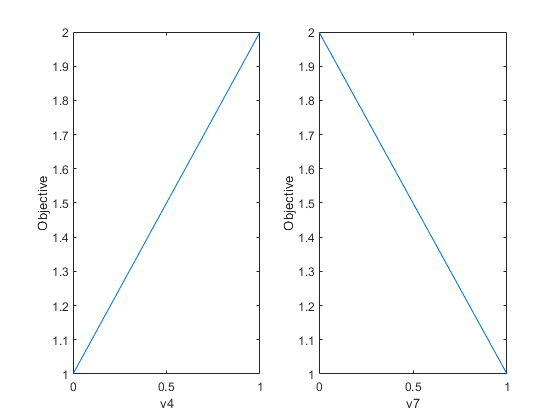

Robustness analysis in progress ...
100%    [........................................]


ans =          0
    0.1111
    0.2222
    0.3333
    0.4444
    0.5556
    0.6667
    0.7778
    0.8889
    1.0000


subplot(1,2,2)
robustnessAnalysis(model,{'v7'},10)

## Gene deletion study

single gene deletion study

model = changeRxnBounds(model,{'v1'},[0],'l'); %reset lower bound to zero, the bounds are between 0-1
model = changeRxnBounds(model,{'v1'},[1],'u'); %reset lower bound to zero, the bounds are between 0-1

model = changeObjective(model,'v6',1); 


disp([model.rxns num2cell(model.lb) num2cell(model.ub)])

    'v1'    [0]    [   1]
    'v2'    [1]    [   1]
    'v3'    [0]    [1000]
    'v4'    [0]    [1000]
    'v5'    [0]    [1000]
    'v6'    [0]    [1000]
    'v7'    [0]    [1000]




[grRatio,grRateKO,grRateWT] = singleGeneDeletion(model,'FBA')

Single gene deletion analysis in progress ...
100%    [........................................]


grRatio =     0.5000
    0.5000
    0.5000
    0.5000
    1.0000
         0
    1.0000


grRateKO =      1
     1
     1
     1
     2
     0
     2


grRateWT = 2


% double gene deletion study
[grRatio,grRateKO,grRateWT] = doubleGeneDeletion(model,'FBA')

Single deletion analysis to remove lethal genes
Single gene deletion analysis in progress ...
100%    [........................................]
6 non-lethal genes
Double gene deletion analysis
Total of 15 pairs to analyze
Double gene deletion analysis in progress ...
Perc complete	CPU time


grRatio =     0.5000         0    0.5000         0    0.5000         0    0.5000
         0    0.5000         0    0.5000    0.5000         0    0.5000
    0.5000         0    0.5000         0    0.5000         0    0.5000
         0    0.5000         0    0.5000         0         0         0
    0.5000    0.5000    0.5000         0    1.0000         0    1.0000
         0         0         0         0         0         0         0
    0.5000    0.5000    0.5000         0    1.0000         0    1.0000


grRateKO =      1     0     1     0     1     0     1
     0     1     0     1     1     0     1
     1     0     1     0     1     0     1
     0     1     0     1     0     0     0
     1     1     1     0     2     0     2
     0     0     0     0     0     0     0
     1     1     1     0     2     0     2


grRateWT = 2

disp(['_' model.rxns'; model.rxns num2cell(grRateKO)])

    '_'     'v1'    'v2'    'v3'    'v4'    'v5'    'v6'    'v7'
    'v1'    [ 1]    [ 0]    [ 1]    [ 0]    [ 1]    [ 0]    [ 1]
    'v2'    [ 0]    [ 1]    [ 0]    [ 1]    [ 1]    [ 0]    [ 1]
    'v3'    [ 1]    [ 0]    [ 1]    [ 0]    [ 1]    [ 0]    [ 1]
    'v4'    [ 0]    [ 1]    [ 0]    [ 1]    [ 0]    [ 0]    [ 0]
    'v5'    [ 1]    [ 1]    [ 1]    [ 0]    [ 2]    [ 0]    [ 2]
    'v6'    [ 0]    [ 0]    [ 0]    [ 0]    [ 0]    [ 0]    [ 0]
    'v7'    [ 1]    [ 1]    [ 1]    [ 0]    [ 2]    [ 0]    [ 2]



## sdsd

dsddssd

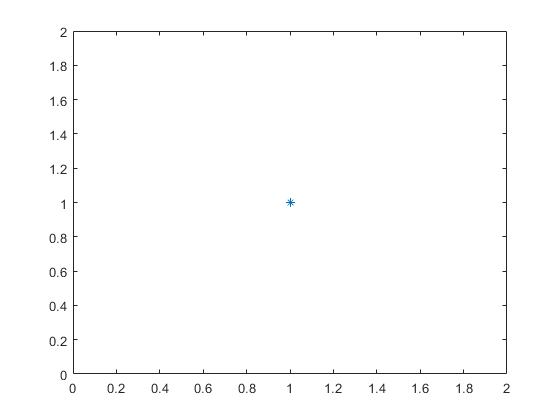

figure
plot(1,1,'*')

Discussion: dffsfdgsd